# Simulation

a               = 0.0;
q               = 0.125;
m               = 2.0;
RF_frequency    = 10.0e+6;


end_time        = double(50.0e+6 / RF_frequency);
maxdist         = 1.0e-5;

vyy1            = 0.1;
yy1             = -0.1;

result = try_mathieu_aq(a, q, m, RF_frequency, end_time, maxdist, yy1, vyy1);

RF frequency = 10.0 MHz
RF amplitude = -81.8 V
DC offset    = 0.0 V
a_r          = 0
q_r          = 0.125
Simulation took 0.0191s (7390567 it/s)


fprintf("Ion lifetime in trap  was %.3g us (%d%% of the total simulation time)\n", ...
    result.lifetime, round(100.0 * result.lifetime / end_time))

Ion lifetime in trap  was 5 us (100% of the total simulation time)


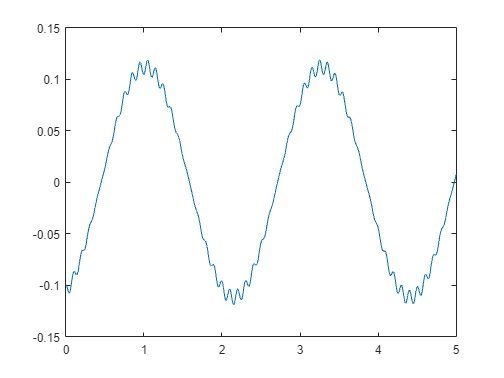

if result.its == 2^20
    fprintf("Simulation was terminated early due to max timestep limit (2^20) being reached.\n")
end
plot(result.ts, result.y_traj);

# Comparison to numerical solution

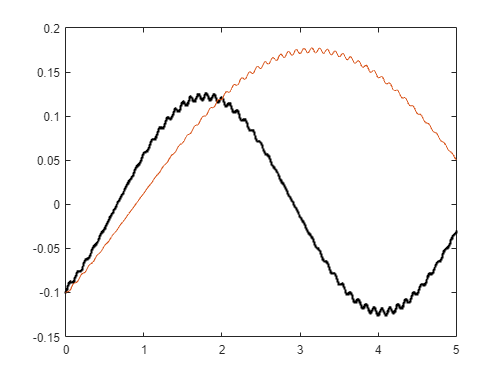

w = 2 * pi * RF_frequency;

x0 = [yy1; vyy1 * (2.0e+6)/w];
[tau, x] = ode45(@(tau, y) mathieu(tau, y, a, q), [0, (1.0e-6) * end_time * w / 2], x0, ...
                 odeset('RelTol', 1.0e-12));

plot(end_time * tau / ((1.0e-6) * end_time * w / 2), x(:,1), '.k')

hold on
plot(result.ts, result.y_traj);
hold off

function dydt = mathieu(tau, y, a, q)
  dydt = [y(2); (a - 2*q*cos(2*tau)) * y(1)];
end